
 tdata=0.004

tdata = 0.0040

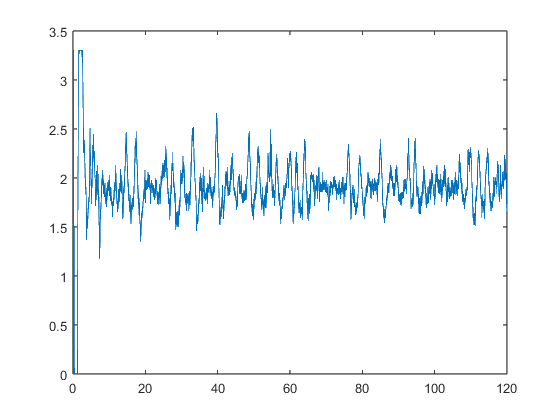

 load('data_t.mat')
  
 data_test1=data_t.eeg1;
 data_test2=data_t.emg1;
 
 data_test2=data_test2*(3.3/4096);
 data_test1=data_test1*(3.3/4096);
 data_test3=data_t.eeg2;
 data_test3=data_test3*(3.3/4096);
  fdata=length(data_test1)/120;
  tdata=1/fdata;
  T_data=[0:1:(18420-1)]*tdata;
  figure;plot(T_data,data_test1)

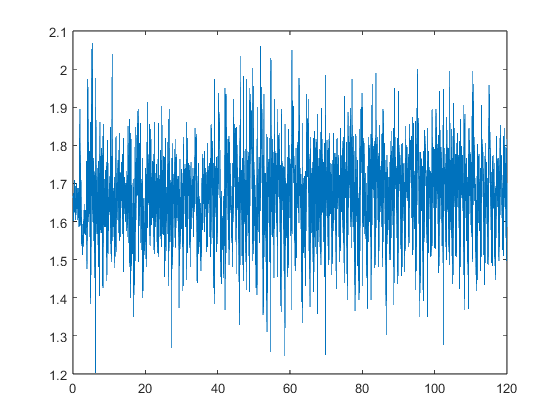

  figure;plot(T_data,data_test2)

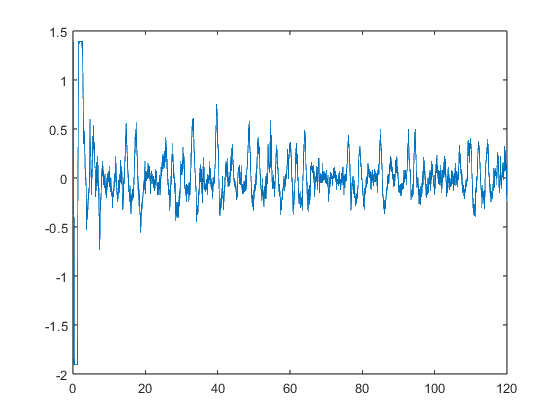

 %removing dc component
  data_test1fft=fft(data_test1);
data_test1fft(1)=0;
data_test1=ifft(data_test1fft);
plot(T_data,data_test1)

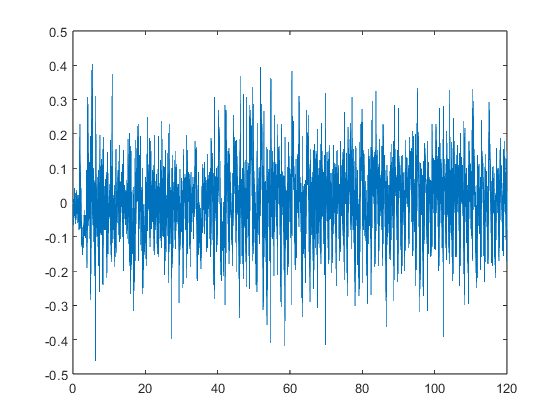

data_test1fft=fft(data_test2);
data_test1fft(1)=0;
data_test2=ifft(data_test1fft);
figure;plot(T_data,data_test2)

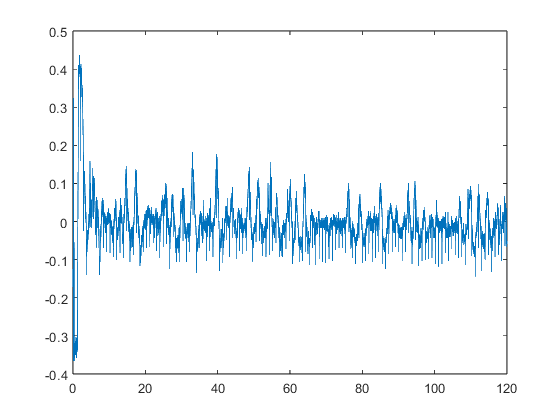

data_test1fft=fft(data_test3);
data_test1fft(1)=0;
data_test3=ifft(data_test1fft);
figure;plot(T_data,data_test3)

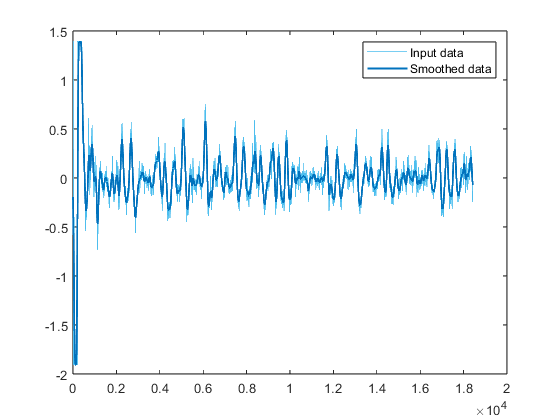

% Smooth input data
smoothedData1 = smoothdata(data_test1,"gaussian","SmoothingFactor",0.2);

% Display results
clf
plot(data_test1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData1,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

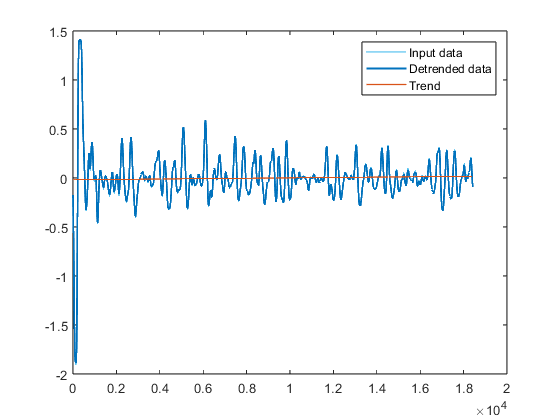

% Remove trend from data
smoothedData2 = detrend(smoothedData1);

% Display results
clf
plot(smoothedData1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(smoothedData1-smoothedData2,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

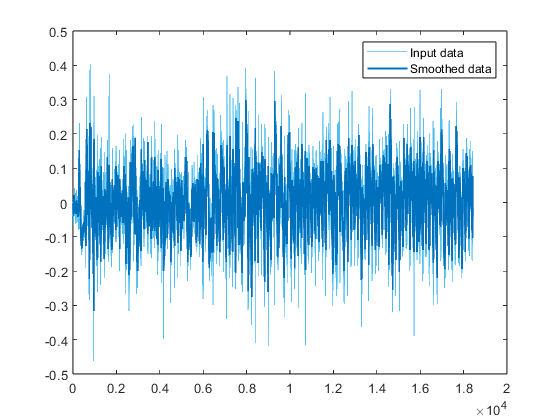

% Smooth input data
smoothedData2 = smoothdata(data_test2,"movmean","SmoothingFactor",0.25);

% Display results
clf
plot(data_test2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

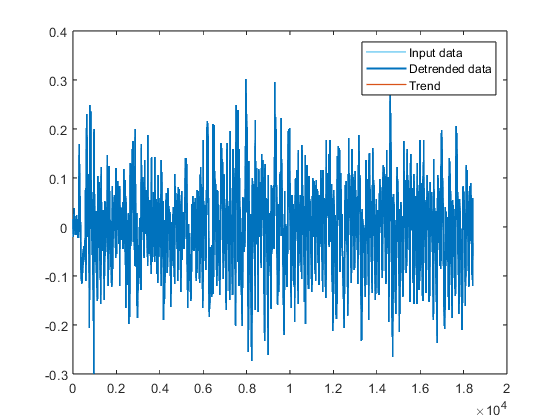

% Remove trend from data
smoothedData2 = detrend(smoothedData2);

% Display results
clf
plot(smoothedData2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(smoothedData2-smoothedData2,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

%t1,data_test2);
% pspectrum(corr_data,fdata,"power",FrequencyLimits=[0,20]);
% % corr_data_pwr=xcorr2(pdeeg1,pdeeg2);
% auto_data1=autocorr(data_test1);
% auto_data2=autocorr(data_test2);
% plot(corr_data_pwr)

% plot(auto_data1);

% pspectrum(auto_data1,fdata,"power",'MinThreshold',0,"FrequencyLimits",[0,20])

% pspectrum(corr_data,fdata,"power",FrequencyLimits=[0,20]);

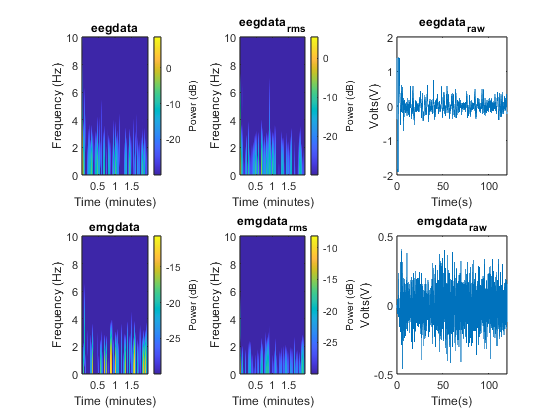

figure;

 title('50 overlap')
subplot(2,3,1)
pspectrum(data_test1,fdata,'spectrogram','TimeResolution',1,'overlapPercent',90,'MinThreshold',-30,FrequencyLimits=[0,10]);title('eegdata');
subplot(2,3,2)
pspectrum(sqrt((data_test1).^2-(data_test3).^2),fdata,'spectrogram','MinThreshold',-30,'TimeResolution',1,'overlapPercent',90,FrequencyLimits=[0,10]); title('eegdata_r_m_s');

subplot(2,3,3)
plot(T_data,data_test1);title('eegdata_r_a_w');
subplot(2,3,4)
pspectrum(data_test2,fdata,'spectrogram','TimeResolution',1,'overlapPercent',90,'MinThreshold',-30,FrequencyLimits=[0,10]);title('emgdata');
subplot(2,3,5)
pspectrum(sqrt((data_test2).^2-(data_test3).^2),fdata,'spectrogram', 'TimeResolution',1,'overlapPercent',90,'MinThreshold',-30,FrequencyLimits=[0,10]);title('emgdata_r_m_s');
subplot(2,3,6)


plot(T_data,data_test2);title('emgdata_r_a_w');
subplot(2,3,3)
xlabel('Time(s)')
ylabel('Volts(V)')
subplot(2,3,6)
xlabel('Time(s)')
ylabel('Volts(V)')

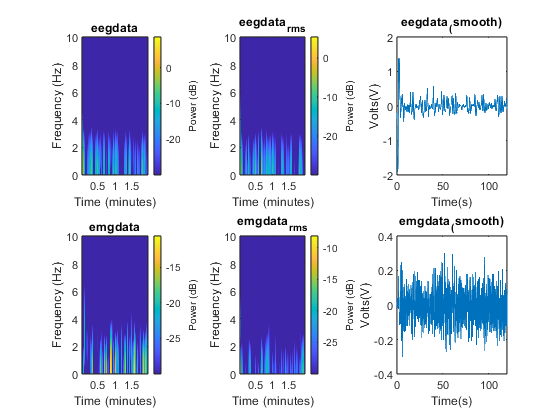

figure;

 title('50 overlap')
subplot(2,3,1)
pspectrum(smoothedData1,fdata,'spectrogram','TimeResolution',1,'overlapPercent',90,'MinThreshold',-30,FrequencyLimits=[0,10]);title('eegdata');
subplot(2,3,2)
pspectrum(sqrt((smoothedData1).^2-(data_test3).^2),fdata,'spectrogram','MinThreshold',-30,'TimeResolution',1,'overlapPercent',90,FrequencyLimits=[0,10]); title('eegdata_r_m_s');

subplot(2,3,3)
plot(T_data,smoothedData1);title('eegdata_(smooth)');
subplot(2,3,4)
pspectrum(smoothedData2,fdata,'spectrogram','TimeResolution',1,'overlapPercent',90,'MinThreshold',-30,FrequencyLimits=[0,10]);title('emgdata');
subplot(2,3,5)
pspectrum(sqrt((smoothedData2).^2-(data_test3).^2),fdata,'spectrogram', 'TimeResolution',1,'overlapPercent',90,'MinThreshold',-30,FrequencyLimits=[0,10]);title('emgdata_r_m_s');
subplot(2,3,6)


plot(T_data,smoothedData2);title('emgdata_(smooth)');
subplot(2,3,3)
xlabel('Time(s)')
ylabel('Volts(V)')
subplot(2,3,6)
xlabel('Time(s)')
ylabel('Volts(V)')

[pdeeg2,feeg2]=pspectrum(sqrt((data_test2).^2-(data_test3).^2),fdata,'power',FrequencyLimits=[0,10]);
[pdeeg1,feeg1]=pspectrum(sqrt((data_test1).^2-(data_test3).^2),fdata,'power',FrequencyLimits=[0,10]);

[eig_xcorr,time_eig_xcorr]=crosscorr(pdeeg1,pdeeg2);

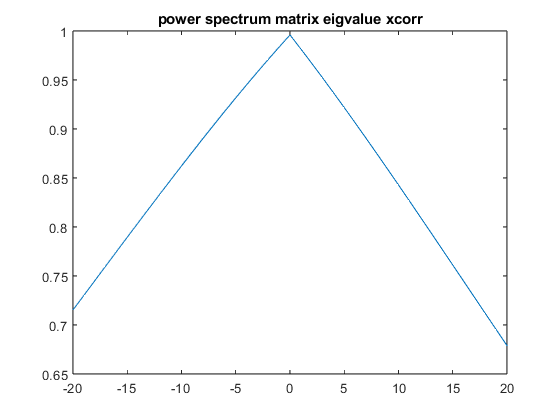

figure;
plot(time_eig_xcorr,eig_xcorr);title('power spectrum matrix eigvalue xcorr');

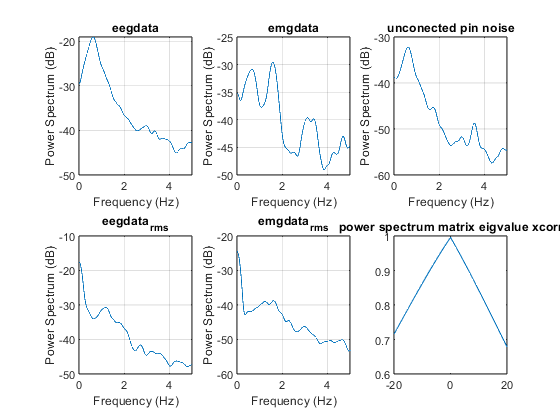

figure;
title('50 overlap')
subplot(2,3,1)
pspectrum(data_test1,fdata,'power',FrequencyLimits=[0,5]);title('eegdata');
subplot(2,3,2)

pspectrum(data_test2,fdata,'power',FrequencyLimits=[0,5]);title('emgdata');
subplot(2,3,3)
pspectrum(data_test3,fdata,'power',FrequencyLimits=[0,5]);title('unconected pin noise');
subplot(2,3,4)
pspectrum(sqrt((data_test1).^2-(data_test3).^2),fdata,'power',FrequencyLimits=[0,5]); title('eegdata_r_m_s');
subplot(2,3,5)
pspectrum(sqrt((data_test2).^2-(data_test3).^2),fdata,'power',FrequencyLimits=[0,5]);title('emgdata_r_m_s');
subplot(2,3,6)
plot(time_eig_xcorr,eig_xcorr);title('power spectrum matrix eigvalue xcorr');

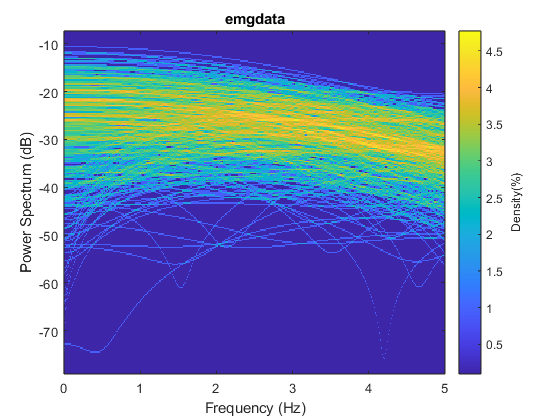

figure;pspectrum(data_test2,fdata,'persistence',FrequencyLimits=[0,5]);title('emgdata');

% figure;
%  title('50 overlap')
% subplot(2,3,1)
% pspectrum(data_test1,fdata,'spectrogram','MinThreshold',3,'TimeResolution',0.5,'overlapPercent',90,FrequencyLimits=[0,15]);title('eegdata');
% subplot(2,3,2)
% 
% pspectrum(data_test2,fdata,'spectrogram','MinThreshold',3,'TimeResolution',0.5,'overlapPercent',90,FrequencyLimits=[0,15]);title('emgdata');
% subplot(2,3,3)
% pspectrum(data_test3,fdata,'spectrogram','MinThreshold',-10,'TimeResolution',0.5,'overlapPercent',90,FrequencyLimits=[0,15]);title('unconected pin noise');
% subplot(2,3,4)
% pspectrum(sqrt((data_test1).^2-(data_test3).^2),fdata,'spectrogram','MinThreshold',3,'TimeResolution',0.5,'overlapPercent',90,FrequencyLimits=[0,15]); title('eegdata_r_m_s');
% subplot(2,3,5)
% pspectrum(sqrt((data_test2).^2-(data_test3).^2),fdata,'spectrogram','MinThreshold',3,'TimeResolution',0.5,'overlapPercent',90,FrequencyLimits=[0,15]);title('emgdata_r_m_s');
% subplot(2,3,6)


% dft_data1=fft(data_test1);
% f_dft=(0:length(dft_data1)-1)*100/length(dft_data1);
% plot(f_dft,dft_data1)

out_sept_12=[data_test1,data_test2];
out_sept_12_smooth=[smoothedData1,smoothedData2];
